


% Question 1 :

% On test la fct Cholesky avce un exemple
    
% Définir la diagonale principale et la sous-diagonale de B
dp = [4; 10; 3];  % Diagonale principale
ds = [2; 2];      % Sous-diagonale
b = [1; 2; 3];    % Vecteur des termes indépendants
    
% Appeler la fonction de Cholesky pour résoudre Bx = b
x = Choleskytri(dp, ds, b);
    
% Afficher la solution x
disp('Solution x :');

Solution x :


disp(x);

    0.2826
   -0.0652
    1.0435



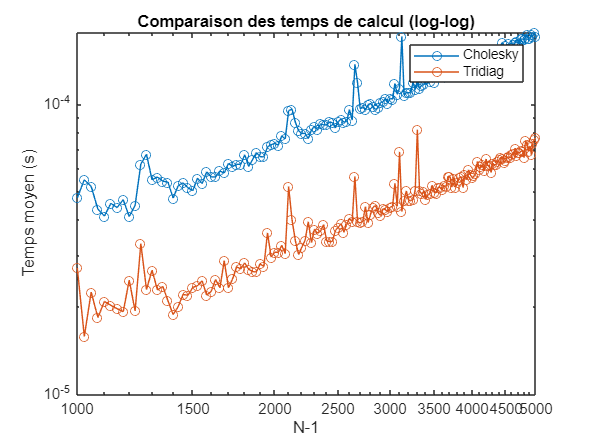



% Questions 2 et 3:

% Initialisation
N_values = 1001:25:5001;  
num_experiments = 500;    
time_Cholesky = [];       % Temps de calcul moyen pour Cholesky
time_Tridiag = [];        % Temps de calcul moyen pour Tridiag

norm_errors = []; % Utilisee pour calcul de la norme infinie

for N = N_values    
    dx = 1 / N; % Pas de discrétisation
    x = linspace(dx, 1-dx, N-1)';

    % Matrice B
    dp = (2 / dx^2 + 1) * ones(N-1, 1); % Diagonale principale
    ds = -1 / dx^2 * ones(N-2, 1);   % Diagonale inférieure
    c = -1 / dx^2 * ones(N-2, 1);    % Diagonale supérieure (pour tridiag1)

    % Vecteur f
    f = sin(pi * x);

    % Solution exacte de v (calculee dans la partie exos qst 1):
    v_exact = -sin(pi * x) / (pi^2 + 1);

    % Résolution avec Choleskytri
    t_Cholesky = 0;  % Temps total pour Cholesky
    for exp = 1:num_experiments
        tic; % On actionne le chronometre
        v_Cholesky = Choleskytri(dp, ds, -f);
        t_Cholesky = t_Cholesky + toc; % On enregistre le temps enregiste par le chrono
    end
    time_Cholesky(end+1) = t_Cholesky / num_experiments;  % Temps moyen de calcul avec Cholesky

    % Calcul de la norme infinie de l'erreur
    norm_inf = max(abs(v_Cholesky - v_exact));
    norm_errors(end+1) = norm_inf; 


    % Résolution avec tridiag1 
    t_Tridiag = 0; 
    for exp = 1:num_experiments
        tic;
        v_Tridiag = tridiag1(dp, ds, c, -f);
        t_Tridiag = t_Tridiag + toc;
    end
    time_Tridiag(end+1) = t_Tridiag / num_experiments;  % Temps moyen

    %fprintf('N = %d, Norme infinie = %.10f\n', N, norm_inf);

end

% On ignore les premières petites valeurs de N pour mieux ajuster alpha
N_filtered = N_values(10:end);
time_Cholesky_filtered = time_Cholesky(10:end);  
time_Tridiag_filtered = time_Tridiag(10:end);

% Ajustement de la dépendance T ~ (N-1)^alpha
alpha_Cholesky = polyfit(log(N_filtered - 1), log(time_Cholesky_filtered), 1);
alpha_Tridiag = polyfit(log(N_filtered - 1), log(time_Tridiag_filtered), 1);

% Tracer les résultats sur un graphique log-log
figure;
loglog(N_values - 1, time_Cholesky, '-o', 'DisplayName', 'Cholesky');
hold on;
loglog(N_values - 1, time_Tridiag, '-o', 'DisplayName', 'Tridiag');
xlabel('N-1');
ylabel('Temps moyen (s)');
legend show;
title('Comparaison des temps de calcul (log-log)');


% Affichage des résultats de l'ajustement
fprintf('Dépendance Cholesky: T ~ (N-1)^%.2f\n', alpha_Cholesky(1));

Dépendance Cholesky: T ~ (N-1)^0.92


fprintf('Dépendance Tridiag: T ~ (N-1)^%.2f\n', alpha_Tridiag(1));

Dépendance Tridiag: T ~ (N-1)^0.91




% On determine beta via la relation cN^beta:
log_N = log(N_values);
log_norm_errors = log(norm_errors);
beta_fit = polyfit(log_N, log_norm_errors, 1);

fprintf('Dépendance de l''erreur: ||e_N||inf ~= cN^%.2f\n', beta_fit(1));

Dépendance de l'erreur: ||e_N||inf ~= cN^-2.00


Commentaire sur comment se comportent les temps de calcul en fonction de N (Question 2) : 

On remarque que le temps de calcul pour les deux methodes augmenent de maniere quasi-lineaire (alpha ~=1) lorsque le N augmente; avec quand meme un temps de calcul un plus eleve avec la methode de Cholesky que celle de Crout, toute deux aux alentours de 10**-4 secondes. On a donc une complexite O(N) pour ces deux methodes.

Commentaire sur la valeur calculée de β (Question 3) : 

On a un beta= -2 , ce qui indique que l'erreur de discrétisation décroît de manière quadratique en fonction de la taille de la discrétisation/ du nombres de poinst N.  Ce qui signifie que si la taille de la discrétisation N double, l'erreur est divisée par un facteur de 4, ce qui implique une tres bonne convergence vers notre solution avec la methode de Cholesky.